## First Test with Good Wheel

clear;clc;clf
[y_true,Fs] = audioread("data/Trial 1/True wheel.m4a");

true_pluck = y_true;
t_true = linspace(0,length(true_pluck)/Fs,length(true_pluck));
% plot(t_true, true_pluck)
% title("One True Pluck Sound");
% ylabel("Amplitude");
% xlabel("Time (s)");
% sound(true_pluck, Fs)

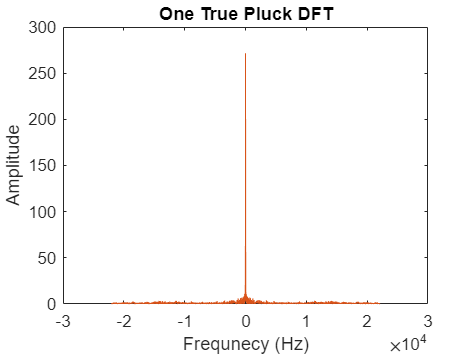

true_N = length(true_pluck);
true_f = linspace(-Fs/2, Fs/2 - Fs/true_N, true_N) + Fs/(2*true_N)*mod(true_N, 2);

true_pluckfft = fft(abs(true_pluck));

true_shiftpluckfft = fftshift(abs(true_pluckfft));

plot(true_f, true_shiftpluckfft)
title("One True Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")

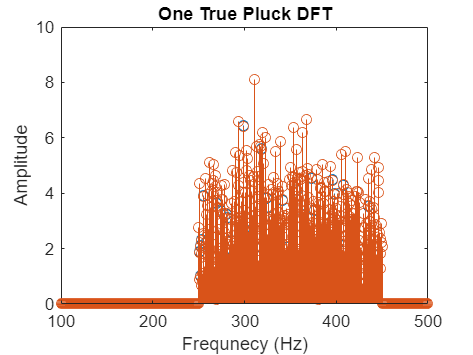




filter = zeros(length(true_f), 1);
filter(true_f >= 250 & true_f <= 450) = 1;

filtered_true = true_shiftpluckfft .* filter;


stem(true_f, filtered_true)
title("One True Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")
xlim([100 500])

## First Test with Bad Wheel

[y_bad,Fs] = audioread("data/Trial 1/Bad wheel .m4a");

bad_pluck = y_bad(1.19*Fs:1.8*Fs);
t_bad = linspace(0,length(bad_pluck)/Fs,length(bad_pluck));
% plot(t_bad, bad_pluck)
% title("One Bad Pluck Sound");
% ylabel("Amplitude");
% xlabel("Time (s)");
% sound(bad_pluck, Fs)

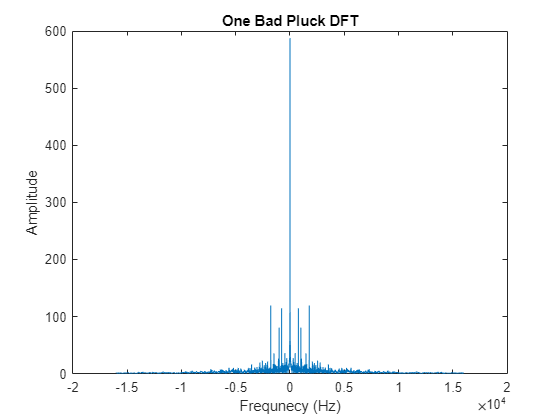

bad_N = length(bad_pluck);
bad_f = linspace(-Fs/2, Fs/2 - Fs/bad_N, bad_N) + Fs/(2*bad_N)*mod(bad_N, 2);

bad_pluckfft = fft(abs(bad_pluck));

bad_shiftpluckfft = fftshift(abs(bad_pluckfft));

plot(bad_f, bad_shiftpluckfft)
title("One Bad Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")

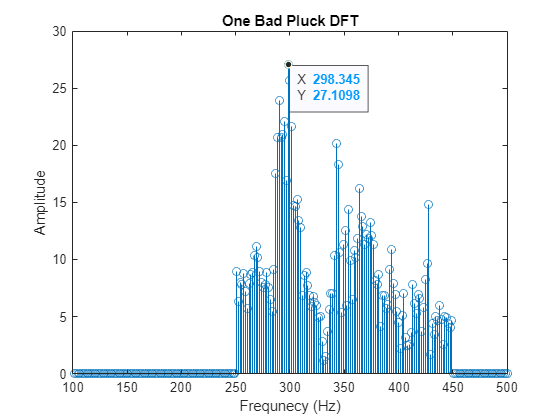



filter = zeros(length(bad_f), 1);
filter(bad_f >= 250 & bad_f <= 450) = 1;

filtered_bad= bad_shiftpluckfft .* filter;

stem(bad_f, filtered_bad)
title("One Bad Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")
xlim([100 500])